syms x(t) y(t) vx(t) vy(t) ax(t) ay(t)

y(t) = int(vy, 0, t)

$$y(t) = \int_{0}^{t}\mathrm{vy}\left(t\right)\mathrm{d}t$$

vy(t) = int(ay, 0, t)

$$vy(t) = \int_{0}^{t}\mathrm{ay}\left(t\right)\mathrm{d}t$$

x(t) = int(vx, 0, t)

$$x(t) = \int_{0}^{t}\mathrm{vx}\left(t\right)\mathrm{d}t$$

vx(t) = int(ax, 0, t)

$$vx(t) = \int_{0}^{t}\mathrm{ax}\left(t\right)\mathrm{d}t$$


ax(t) = (-9.8 / sqrt(y(t)^2 + x(t)^2)) * x(t)

$$ax(t) = -\frac{49\,\int_{0}^{t}\mathrm{vx}\left(t\right)\mathrm{d}t}{5\,\sqrt{{\int_{0}^{t}\mathrm{vx}\left(t\right)\mathrm{d}t}^{2}+{\int_{0}^{t}\mathrm{vy}\left(t\right)\mathrm{d}t}^{2}}}$$

ay(t) = (-9.8 / sqrt(y(t)^2 + x(t)^2)) * y(t)

$$ay(t) = -\frac{49\,\int_{0}^{t}\mathrm{vy}\left(t\right)\mathrm{d}t}{5\,\sqrt{{\int_{0}^{t}\mathrm{vx}\left(t\right)\mathrm{d}t}^{2}+{\int_{0}^{t}\mathrm{vy}\left(t\right)\mathrm{d}t}^{2}}}$$

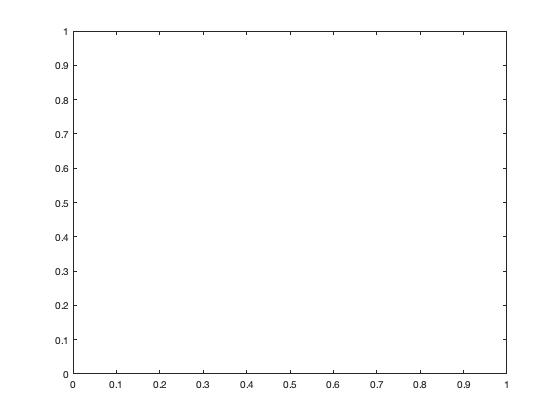

fplot(x, y)

[T, D] = ode45(@rate_func, [0, 100], [50, 50, 50, 50]);

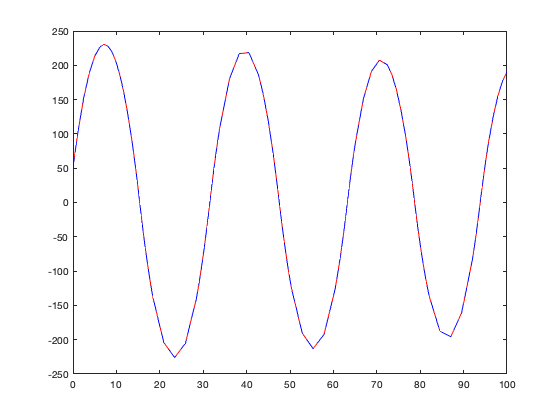

plot(T, D(:, 1), "r"); hold on;
plot(T, D(:, 2), "b--"); hold off;

function res = rate_func(~, vals)
    [x, y, vx, vy] = matsplit(vals);
    
    dxdt = vx;
    dydt = vy;
    
    scale_factor = -9.8 / sqrt(y^2 + x^2);
    
    ax = scale_factor * x;
    ay = scale_factor * y;
    
    res = [dxdt; dydt; ax; ay];
end